-  Batch and Recursive 

    Let us samples data ${(x_1 ,x_2 ,..., x_i ,..., x_n )} $ at sampled time $t_i , i = 1,2,...,n$.  Calculate the average of the Data. 

  1. Batch calculation and recursive 

   Batch process

    
$$x_{av}  = 1/n \sum_{i=1}^{n} x_i $$


   and recuresive  processing is  as follows

    Define 


$$S_k = 1/k \sum_{i = 1}^{k}x_i  $$


  Then 


$$s_{k+1}= \frac{1}_{k+1}\sum_{i=1}^{k+1} x_i = \frac{1}_{k+1}x_k+ \frac{1}_{k+1}\sum_{i =1}^{k}x_i \\ =\frac{1}_{k+1}x_k + \frac{k}_{k+1}s_k\\ =\frac{k}_{k+1}s_k + \frac{1}_{k+1} x_{k+1}$$


Let us check 

clear all;  
rng('default')   % seed of random is fixed.
n = 1001;         % number of sampling 
t = linspace(0,1,n);

% batch processing
x = rand(n,1);
xBatch = sum(x)/n

% recursive processing
xRec(1) = x(1);
for i = 1:n-1
    xRec(i+1) =i/(i+1)*xRec(i) + 1/(i+1)*x(i+1);
end
xRec(end)

Hence the value of Batch and recursive are same to each other. Check the differences.  

- Estimation 

If you have a measured data  $z =\{z_1 , z_2 ,..., z_n \}$, which is random,for example measure  the number of n person's height.What is the best estimation of the height? One estimation is the sample average , i.e., 


$$\bar{m}_z  =  \frac{1}_{n} \sum_{i=1}^{n} z_i $$


Or if it is know the pdf of the height, luckly, the mean (or expectration) of the height is 


$$E[Z] = \int \ zf(z)dx$$


Which it the best estimator. 

- **Sum of a Gaussian RV**. 

Consider 


$$z = x+y  \\
x \sim N(\bar{x}, M) \ v ~ \sim N(0, V)$$


Given the sampled data ${(z_1 ,z_2 ,...,z_n )} $ at sampled time $t_i , i = 1,2,...,n$.  Calculate the minimum mean variance estimotor, $E[x|z]$.

First generate a gaussian random variables $x \sim (\bar{x}, M)$. Here  cmd "randn" is used to be checked.

 1. generate a Gauss RV and check the pdf using 'fitdist'  

   Generate a gaussian by cmd "randn(a,b)' to confirm how much it is similar to a real gaussian. 

clear all;  
rng('default')
n = 1000;    % number of sampling 
t = linspace(-10,10,n);
barX = 1;
varX = 1;
x = barX + sqrt(varX)*(randn(n,1));
figure( ); hold on ; grid on;
histogram(x,'Normalization','pdf');% normalize the total sum to be one.
pd = fitdist(x,'Normal');
xPdf =pdf(pd,t);
line(t,xPdf, 'linewidth',3, 'color', 'r')

 So far  the generated RV by " randn" is similar to the specified Gaussian. Hence  the cmd "randn" will be used in fht following lecture without special comment. 

2. Generate a sum of Gaussian which is the sum of two Gauss RVs.

clear all;clf 
rng('default')
n = 1000;    % number of sampling 
t = linspace(0,10,n);
barX = 2;M =1;         % one Gaussain ~ N(2,1)
barV = 0; V =1;    % the other ~ N(0,0.01)

x = barX + sqrt(M)*randn(n,1);   % X ~ N(barX, M)
v = barV + sqrt(V)*randn(n,1);   % v ~ N(barY, V)
z = x + v;

pd_x = fitdist(x,'Normal');
pd_v = fitdist(v,'Normal');
pd_z = fitdist(z,'Normal');

xpdf=pdf(pd_x,t);
vpdf=pdf(pd_v,t);
zPdf=pdf(pd_z,t)

figure( ); 
plot(t,z)
title('measurement z')

figure( ); hold on 
line(t,xpdf,'linewidth', 2,'color','b')
line(t,vpdf,'linewidth',2,'color','k');
line(t,zPdf, 'linewidth',3, 'color', 'r')

In fig. the measured data is shown, which is the sum of the signal  $x$ and the noise.  The estimate pdf of $z$ using histogram is similar to a gaussian. In the theory **it should be a Gaussian.** To estimate signal 

$x$ , it may be average of the measurement, which is mean of $z$,one of the estimator of $x$.   

mean(z)

 which is near to real $E[X]$. 

- Estimation - conditional expectation

Now in general, to sense or measure a specific object, it is corrupted by the noise, 

                                                          
$$z=\textrm{Hx}+v$$


hence the real value of the object may be estimated by the measurement, i.e., 

                                           
$$\overset{\sim \;}{x} =\textrm{estimator}\;\textrm{of}\;x\;\;\;\textrm{given}\;\textrm{the}\;\textrm{measurement}\;z$$


The problem is how to select the estimator  in some optimal sense.

1)  Frequentist way

     In the above example, 

                                                          
$$E\left\lbrack z\right\rbrack =H\;E\left\lbrack x\right\rbrack$$


is one of the estimator, here the sampled average is used to get E[z] , consider 1-D case

                                     
$$\begin{array}{l}
\bar{z} =\frac{1}{n\;}\sum_{i=1} z_{i\;} \;=\frac{1}{n\;}\;\sum_{i=1} \left(x_i +v_{i\;} \right)\;,\\
x~N\left(\bar{x\;} ,\sigma_{x\;}^{2\;} \right)=N\left(2,1^2 \right)\;,\;v~N\left(0,\sigma_v^2 \right)=N\left(0,0\ldotp 1^2 \right)
\end{array}$$


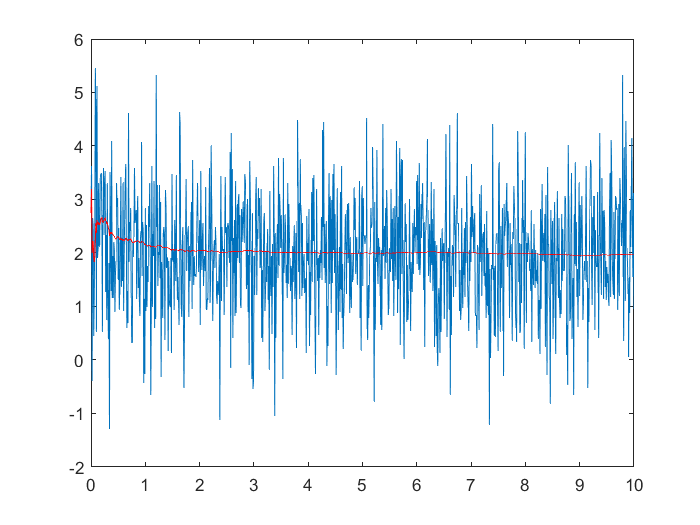

clear all;clf 
rng('default')
n = 1000;    % number of sampling 
t = linspace(0,10,n);
barX = 2; M =1;         % one Gaussain ~ N(2,1)
barV = 0; V =0.1;    % the other ~ N(0,0.01)

x = barX + sqrt(M)*randn(n,1);   % X ~ N(barX, M)
v = barV + sqrt(V)*randn(n,1);   % v ~ N(barY, V)
z = x + v;
samZ(1) = z(1);
for i = 1:n-1
    samZ(i+1) =i/(i+1)*samZ(i) + 1/(i+1)*z(i+1);
end
plot(t,z); hold on 
plot(t, samZ,'r');
hold off

however, to get $E\left\lbrack z\right\rbrack$ it is needed the pdf of $z$ or sampled many times to get an sampled  mean, which are difficult due to the deficiency of pdf or real time processing.

 2) Bayesian way 

   Now given the measurement $z$ , the problem is to estimate $x$ in some optimal sense. Here consider one of the popular criterior to choose the estimator, the minimum mean square error estimator as

                                                  
$$\hat{x\;} =\arg_a \;\min \;E\left\lbrack {\left(x-a\right)}^2 \left|z\right.\right\rbrack$$


which is turned to the conditional expectation of x, i.e., 

                                                
$$\hat{x\;} =\arg_a \;\min \;E\left\lbrack {\left(x-a\right)}^2 \left|z\right.\right\rbrack =E\left\lbrack x\left|z\right.\right\rbrack$$


Wow... But to get the condtional expectation the conditioned pdf is needed. 

If two random variables are gaussian, it is solved as 

                                                
$$E\left\lbrack x\left|z\right.\right\rbrack =m_x +K\;\left(z-m_{x\;} \right)$$


Here 

                                               
$$K\;={\left(M^{-1\;} +H^T V^{-1} H\;\right)}^{-1} H^T V^{-1\;}$$


   a) Batch method 

 Now the MV, $E[x|z] $ is derived **recursively. **

2. Calculate the kalman gain 

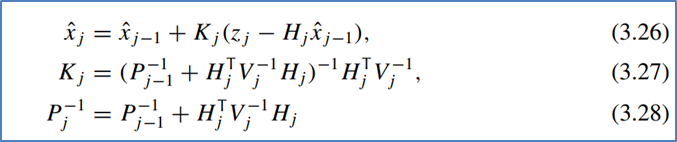

 Here matlab code

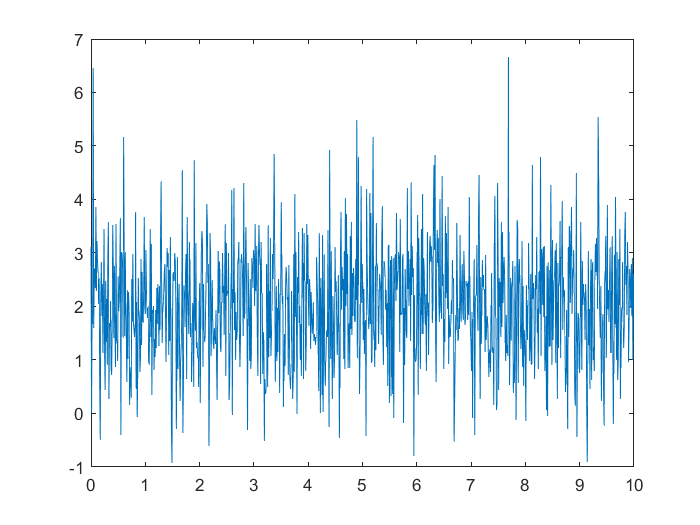

clear all;
rng('default')
n = 1000;    % number of sampling 
t = linspace(0,10,n);
mX = 2; M = 1;      
mV = 0; V = 0.1;   

% barX = mX; M= varX;  
% barV = mV; V = varV;

% initialization 
estX(1) = 2;  P = M;

for i = 1:n
        
    K = inv(inv(P) + inv(V))*V;
    P= inv(inv(P) + inv(V));
    
    x(i) = mX + sqrt(M)*randn(1,1);
    v(i) = mV + sqrt(V)*randn(1,1);    
    z(i) = x(i) + v(i);
    
    estX(i+1) = estX(i) + K*(z(i)-estX(i));
end 

figure(1)
plot(t,z); hold on

% plot(t,estX(1:end-1), 'linewidth',2,'color','r'); 

In this code, $E[x|z] \sim  E[x]  $ in 1 sec later. So far it is good. Moreover in the initialization, it is difficult to estimate of the real state $x$. In general it is assumed 


$$\bar{x}(0) = 0 $$


In the case of this still $E[x|z] \sim E[x] $ in a second.  And the variance of the signal $x$ is assumed to 10 times of the real one, still it is good. So far , even if the initail guess for the real stae is not the same, still the estimator using Kalman gain is  a good, more over the minimum mean square error estimator in this linear sum of two RV's.  